## final module project 7

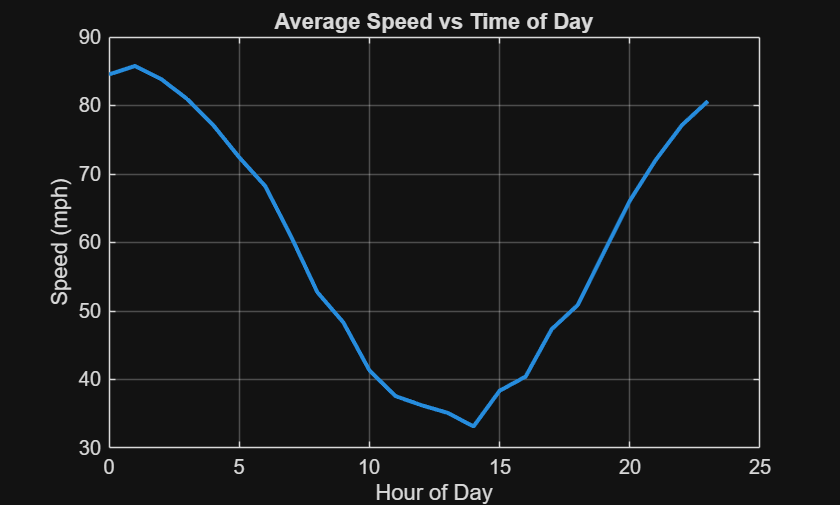

%% Project 7: Traffic Flow & Congestion Patterns
% This script:
% 1. Generates synthetic hourly traffic volume & speed data for multiple days
% 2. Computes congestion indicators
% 3. Visualizes traffic patterns
% 4. Identifies best off-peak travel windows

clc; clear; close all;

%% ---------------------------------------------------------
% 1. SYNTHETIC HOURLY DATA FOR MULTIPLE DAYS
% ----------------------------------------------------------

hours = 0:23;           % 24 hours
days = 1:7;             % 7 days (Mon–Sun)

[H, D] = meshgrid(hours, days);

% Synthetic traffic volume (vehicles/hour)
volume = 400 + 300*sin((H-7)/24*2*pi) + 150*rand(size(H));
volume = max(volume, 50);   % no negative values

% Synthetic speed (mph)
speed = 65 - 25*sin((H-7)/24*2*pi) - 10*rand(size(H));
speed = max(speed, 5);

%% ---------------------------------------------------------
% 2. CONGESTION INDICATOR
% ----------------------------------------------------------
% Congestion = high volume + low speed
% Normalize both to 0–1 scale

vol_norm = (volume - min(volume(:))) / (max(volume(:)) - min(volume(:)));
spd_norm = 1 - (speed - min(speed(:))) / (max(speed(:)) - min(speed(:)));

congestion = 0.6*vol_norm + 0.4*spd_norm;   % weighted indicator

%% ---------------------------------------------------------
% 3. VISUALIZATIONS
% ----------------------------------------------------------

% Speed vs Time (average across days)
figure;
plot(hours, mean(speed,1), 'LineWidth', 2)
xlabel('Hour of Day')
ylabel('Speed (mph)')
title('Average Speed vs Time of Day')
grid on

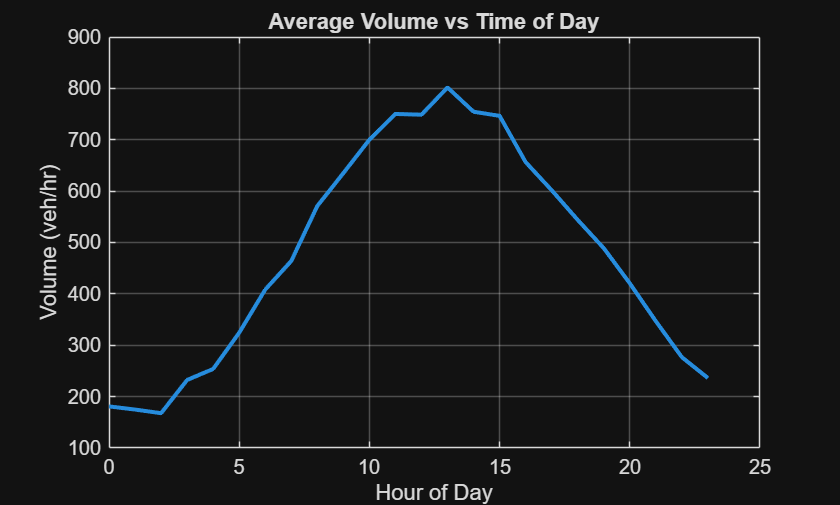


% Volume vs Time (average across days)
figure;
plot(hours, mean(volume,1), 'LineWidth', 2)
xlabel('Hour of Day')
ylabel('Volume (veh/hr)')
title('Average Volume vs Time of Day')
grid on

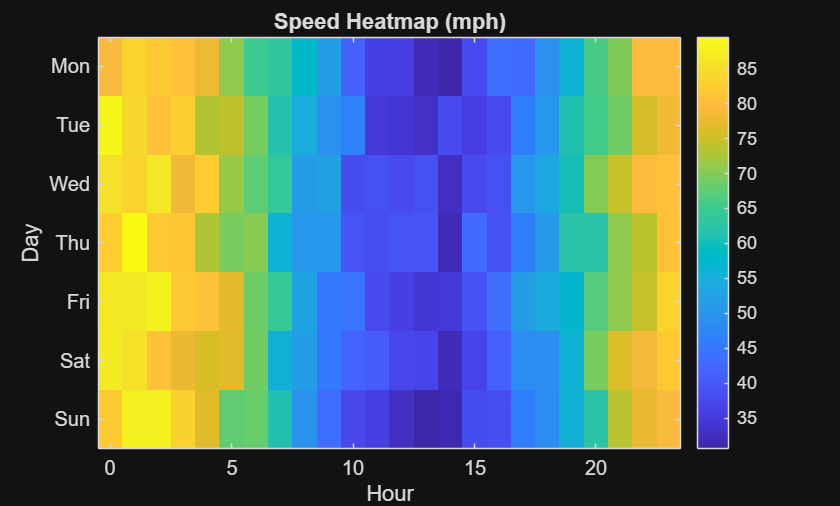


% Weekday comparison (speed heatmap)
figure;
imagesc(hours, days, speed)
colorbar
xlabel('Hour')
ylabel('Day')
title('Speed Heatmap (mph)')
set(gca,'YTick',1:7,'YTickLabel',{'Mon','Tue','Wed','Thu','Fri','Sat','Sun'})

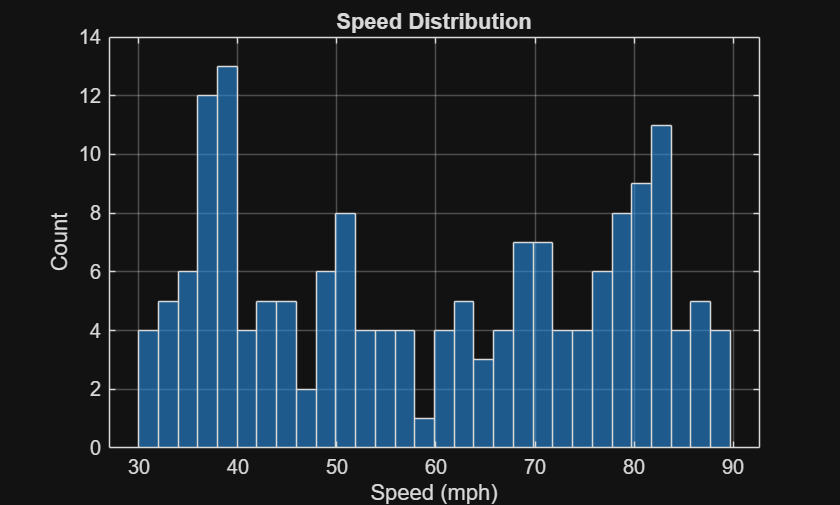


% Distribution of speeds
figure;
histogram(speed(:), 30)
xlabel('Speed (mph)')
ylabel('Count')
title('Speed Distribution')
grid on


%% ---------------------------------------------------------
% 4. IDENTIFY OFF-PEAK WINDOWS
% ----------------------------------------------------------

% Average congestion by hour
avg_cong = mean(congestion,1);

% Find hours with lowest congestion
[~, sorted_idx] = sort(avg_cong);
best_hours = sorted_idx(1:3);   % top 3 off-peak hours

%% ---------------------------------------------------------
% PRINT RESULTS
% ----------------------------------------------------------

fprintf('Best off-peak travel hours (lowest congestion):\n');

Best off-peak travel hours (lowest congestion):


disp(best_hours)

     2     3     1




fprintf('Average congestion values for these hours:\n');

Average congestion values for these hours:


disp(avg_cong(best_hours))

    0.0759    0.0829    0.0894

